T= readtable("C:\Users\user\MATLAB\Projects\untitled\resources\project\EskomAnalysisFold\South Africa Load data TN.xlsx","VariableNamingRule", "preserve",'PreserveVariableNames',true);
T.Properties.VariableNames={'Date','Hour','Day','NettSentout'};

if ~isdatetime(T.Date)
    T.Date = datetime(T.Date, 'InputFormat', 'dd-MM-yyyy');
end

% Extract the year and week number from the Date column
T.Year = year(T.Date);
T.Week = week(T.Date);
T.Day = day(T.Date);
T.Month = month(T.Date);
T.Hour =hour(T.Date);


## Daily analysis

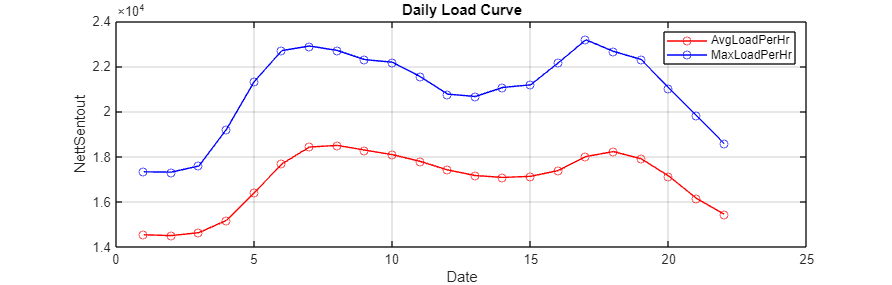

%Calculating load profile for each hour of the day
%Calculating the avg load
avgLoadPerWeek = varfun(@mean, T, "InputVariables","NettSentout","GroupingVariables","Hour");
%Calculating the max load
maxLoadPerWeek = varfun(@max, T, "InputVariables","NettSentout", "GroupingVariables","Hour");

%Plotting the data
figure('Position', [1000, 1000, 2500, 800]);
plot(avgLoadPerWeek.Hour(2:23), avgLoadPerWeek.mean_NettSentout(2:23),  '-o', 'Color','r' ,'DisplayName','AvgLoadPerHr');
xlabel('Date');
ylabel('NettSentout');
title('Daily Load Curve');
grid on;

hold on;
plot(maxLoadPerWeek.Hour(2:23), maxLoadPerWeek.max_NettSentout(2:23),  '-o', 'Color','b', 'DisplayName','MaxLoadPerHr');
legend show;

xtickformat
% Find the highest hourly total for each day in each month
highestHourlyDay = varfun(@max, T, 'GroupingVariables', {'Year', 'Month', 'Day'}, 'InputVariables', 'NettSentout');

% Display the first few rows of the result to verify
disp(head(highestHourlyDay));

    Year    Month    Day    GroupCount    max_NettSentout
    ____    _____    ___    __________    _______________

    1988      1       1         24             14354     
    1988      1       2         24             14119     
    1988      1       3         24             13073     
    1988      1       4         24             15778     
    1988      1       5         24             16276     
    1988      1       6         24             16478     
    1988      1       7         24             16569     
    1988      1       8         24             16842     



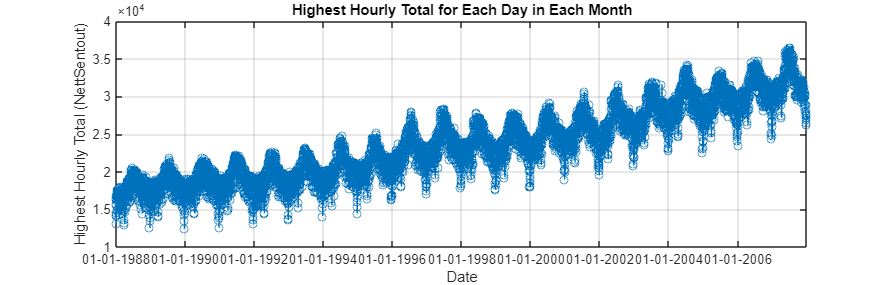

% Convert the year, month, and day columns back to a datetime array
highestHourlyDay.Date = datetime(highestHourlyDay.Year, highestHourlyDay.Month, highestHourlyDay.Day);

%Plot the highest hourly totals
figure('Position', [1000, 1000, 2500, 800]);
plot(highestHourlyDay.Date, highestHourlyDay.max_NettSentout, '-o');
xlabel('Date');
ylabel('Highest Hourly Total (NettSentout)');
title('Highest Hourly Total for Each Day in Each Month');
grid on;
xtickformat('dd-MM-yyyy');

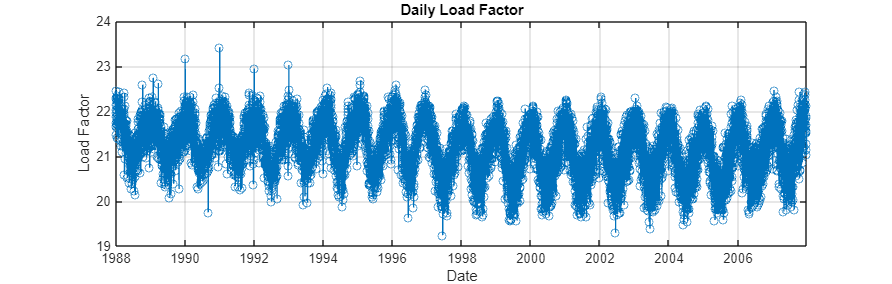

% Calculate Daily Load Factor
% Calculate daily max and sum
maxOfDailyLoad = varfun(@max, T, 'GroupingVariables', {'Year', 'Month', 'Day'}, 'InputVariables', 'NettSentout');
sumOfDailyLoad = varfun(@sum, T, 'GroupingVariables', {'Year', 'Month', 'Day'}, 'InputVariables', 'NettSentout');

% Calculate daily load factor
dailyLoadFactor = table(sumOfDailyLoad.sum_NettSentout ./ maxOfDailyLoad.max_NettSentout, 'VariableNames',{'LoadFactor'});
dailyLoadFactorTable = [maxOfDailyLoad, dailyLoadFactor];
dailyLoadFactorTable.Date = datetime(dailyLoadFactorTable.Year, dailyLoadFactorTable.Month, dailyLoadFactorTable.Day);

% Plot daily load factor
figure('Position', [100, 100, 2200, 700]);
plot(dailyLoadFactorTable.Date, dailyLoadFactorTable.LoadFactor, '-o');
xlabel('Date');
ylabel('Load Factor');
title('Daily Load Factor');
grid on;

## Weekly analysis

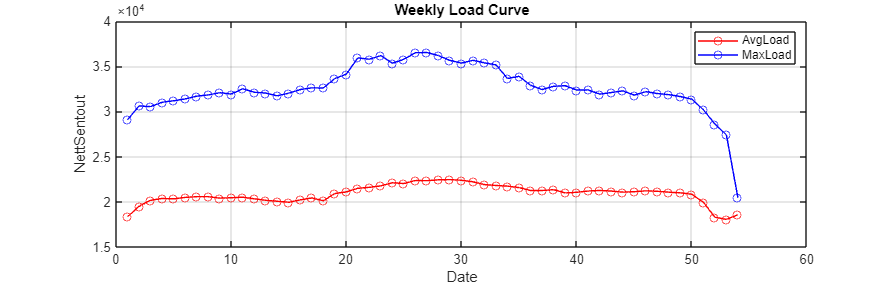

%Calculating the avg load
avgLoadPerWeek = varfun(@mean, T, "InputVariables","NettSentout","GroupingVariables","Week");
%Calculating the max load
maxLoadPerWeek = varfun(@max, T, "InputVariables","NettSentout", "GroupingVariables","Week");

%Plotting the data
figure('Position', [1000, 1000, 2500, 800]);
plot(avgLoadPerWeek.Week, avgLoadPerWeek.mean_NettSentout,  '-o', 'Color','r' ,'DisplayName','AvgLoad');
xlabel('Week');
ylabel('NettSentout');
title('Weekly Load Curve');
grid on;

hold on;
plot(maxLoadPerWeek.Week, maxLoadPerWeek.max_NettSentout,  '-o', 'Color','b', 'DisplayName','MaxLoad');
legend show;

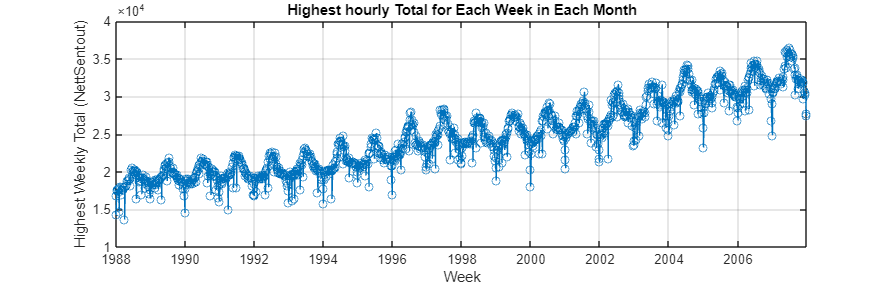


%Find the highest hourly total for each week
highestHourlyWeek = varfun(@max, T,...
    'GroupingVariables', {'Year', 'Month','Week'},...
    'InputVariables', 'NettSentout');
highestHourlyWeek.Date = datetime(highestHourlyWeek.Year, 1, 1) + calweeks(highestHourlyWeek.Week - 1);

% Plot the graph for the highest hour in a week
figure('Position', [1000, 1000, 2500, 800]);
plot(highestHourlyWeek.Date, highestHourlyWeek.max_NettSentout, '-o');
xlabel('Week');
ylabel('Highest Weekly Total (NettSentout)');
title('Highest hourly Total for Each Week in Each Month');
grid on;

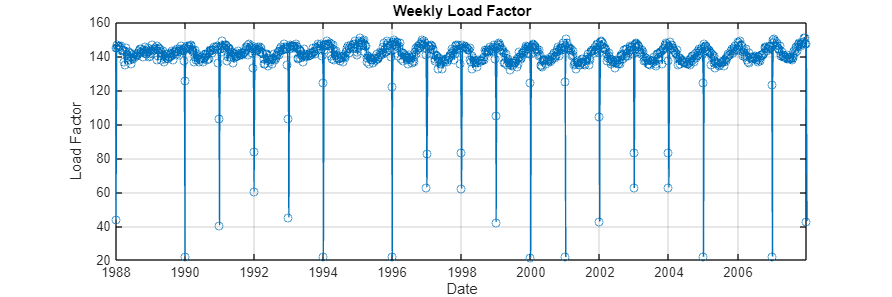

%Calculate Weekly load Factor
% Calculate weekly max and sum
meanOfWeeklyLoad = varfun(@max, T, 'GroupingVariables', {'Year', 'Week'}, 'InputVariables', 'NettSentout');
sumOfWeeklyLoad = varfun(@sum, T, 'GroupingVariables', {'Year', 'Week'}, 'InputVariables', 'NettSentout');

% Calculate weekly load factor
weeklyLoadFactor = table(sumOfWeeklyLoad.sum_NettSentout ./ meanOfWeeklyLoad.max_NettSentout, 'VariableNames',{'LoadFactor'});
weeklyLoadFactorTable = [meanOfWeeklyLoad, weeklyLoadFactor];
weeklyLoadFactorTable.Date = datetime(weeklyLoadFactorTable.Year, 1, 1) + calweeks(weeklyLoadFactorTable.Week - 1);

% Plot weekly load factor
figure('Position', [100, 100, 1200, 400]);
plot(weeklyLoadFactorTable.Date, weeklyLoadFactorTable.LoadFactor, '-o');
xlabel('Date');
ylabel('Load Factor');
title('Weekly Load Factor');
grid on;

## Monthly Analysis

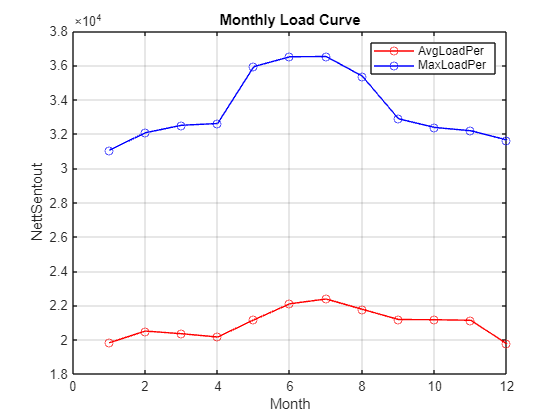

%Calculating the avg load
avgLoadPerMonth = varfun(@mean, T, "InputVariables","NettSentout","GroupingVariables","Month");
%Calculating the max load
maxLoadPerMonth = varfun(@max, T, "InputVariables","NettSentout", "GroupingVariables","Month");

%Plotting the data
figure;
plot(avgLoadPerMonth.Month, avgLoadPerMonth.mean_NettSentout,  '-o', 'Color','r' ,'DisplayName','AvgLoadPer');
xlabel('Month');
ylabel('NettSentout');
title('Monthly Load Curve');
grid on;

hold on;
plot(maxLoadPerMonth.Month, maxLoadPerMonth.max_NettSentout,  '-o', 'Color','b', 'DisplayName','MaxLoadPer');
legend show;

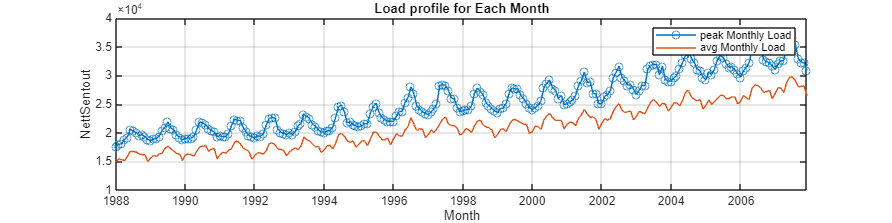


% Calculate the Monthly Load Profile
highestMonthlyPeek = varfun(@max, T, "GroupingVariables", {'Year', 'Month'}, InputVariables="NettSentout");
avgMonthlyLoad = varfun(@mean, T, "GroupingVariables",{'Year', 'Month'}, "InputVariables","NettSentout");

highestMonthlyPeek.Date = datetime(highestMonthlyPeek.Year, highestMonthlyPeek.Month, 1);
avgMonthlyLoad.Date = highestMonthlyPeek.Date;
% Plot the monthly peak load
figure('Position', [2000, 1000, 4000, 1000]);
plot(highestMonthlyPeek.Date, highestMonthlyPeek.max_NettSentout, '-o', 'DisplayName','peak Monthly Load');
xlabel('Month');
ylabel('NettSentout');
title('Load profile for Each Month');
grid on;
xtickformat("yyyy");
hold on;
plot(avgMonthlyLoad.Date, avgMonthlyLoad.mean_NettSentout,'DisplayName', 'avg Monthly Load');
legend show;

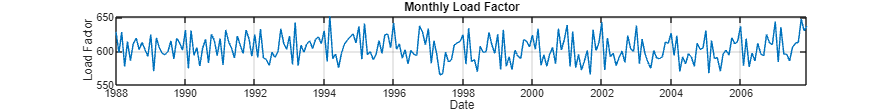

% Calculate monthly max and sum
meanOfMonthlyLoad = varfun(@max, T, 'GroupingVariables', {'Year', 'Month'}, 'InputVariables', 'NettSentout');
sumOfMonthlyLoad = varfun(@sum, T, 'GroupingVariables', {'Year', 'Month'}, 'InputVariables', 'NettSentout');

% Calculate monthly load factor
monthlyLoadFactor = table(sumOfMonthlyLoad.sum_NettSentout ./ meanOfMonthlyLoad.max_NettSentout, 'VariableNames',{'LoadFactor'});
dailyLoadFactorTable = [meanOfMonthlyLoad, monthlyLoadFactor];
dailyLoadFactorTable.Date = datetime(dailyLoadFactorTable.Year, dailyLoadFactorTable.Month, 1);

% Plot monthly load factor
figure('Position', [0, 0, 8000, 1000]);
plot(dailyLoadFactorTable.Date, dailyLoadFactorTable.LoadFactor);
xlabel('Date');
ylabel('Load Factor');
title('Monthly Load Factor');
grid on;

## Yearly Analysis

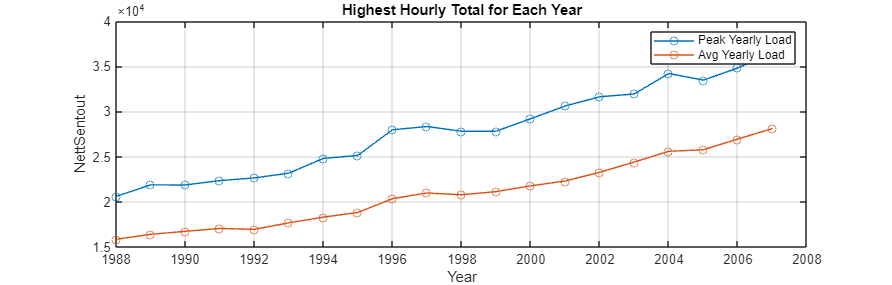



% Find the peak load hours for each year
peakLoadHours = varfun(@max, T, ...
    'GroupingVariables', 'Year', ...
    'InputVariables', 'NettSentout');
avgLoadYearly = varfun(@mean, T, ...
    "InputVariables","NettSentout",...
    "GroupingVariables","Year");

% Plot the yearly profiles
figure("Position",[800, 800, 2500, 800]);
plot(peakLoadHours.Year, peakLoadHours.max_NettSentout, '-o','DisplayName','Peak Yearly Load');
xlabel('Year');
ylabel('NettSentout');
title('Highest Hourly Total for Each Year');
grid on;

hold on;
plot(avgLoadYearly.Year, avgLoadYearly.mean_NettSentout, '-o', 'DisplayName', 'Avg Yearly Load');
legend show;

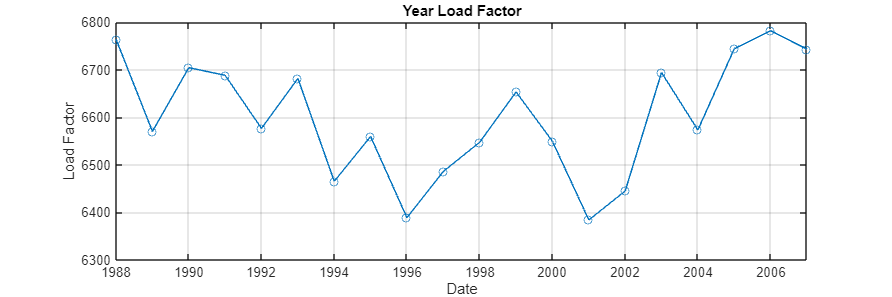

%Calculate Load Factor
% Calculate yearly max and sum
meanOfYearlyLoad = varfun(@max, T, 'GroupingVariables', {'Year'}, 'InputVariables', 'NettSentout');
sumOfYearlyLoad = varfun(@sum, T, 'GroupingVariables', {'Year'}, 'InputVariables', 'NettSentout');

% Calculate yearly load factor
yearlyLoadFactor = table(sumOfYearlyLoad.sum_NettSentout ./ meanOfYearlyLoad.max_NettSentout, 'VariableNames',{'LoadFactor'});
yearlyLoadFactorTable = [meanOfYearlyLoad, yearlyLoadFactor];
yearlyLoadFactorTable.Date = datetime(yearlyLoadFactorTable.Year, 1, 1);

% Plot yearly load factor
figure('Position', [100, 100, 1200, 400]);
plot(yearlyLoadFactorTable.Date, yearlyLoadFactorTable.LoadFactor, '-o');
xlabel('Date');
ylabel('Load Factor');
title('Year Load Factor');
grid on;

## Load data trends, seasonal and residual components

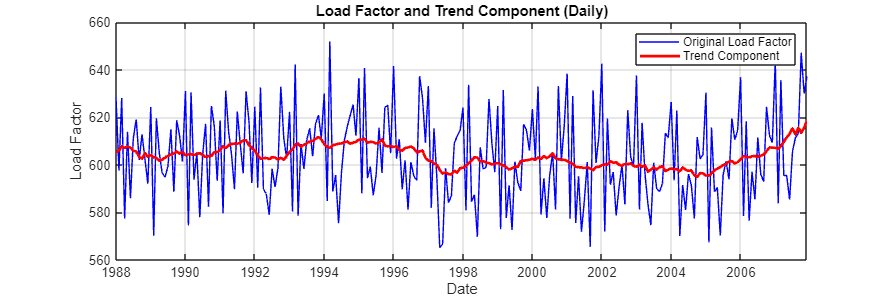

% Calculation using simple moving average
monthlyLoadFactorTrend = movmean(dailyLoadFactorTable.LoadFactor, 12);
% Add daily trend to the table
dailyLoadFactorTable.yearlyTrend = monthlyLoadFactorTrend;

% de-trend the data
deTrendedMonthlyLoadFactor = dailyLoadFactorTable.LoadFactor - monthlyLoadFactorTrend;

% Plot the data
figure('Position', [100, 100, 1200, 400]);
plot(dailyLoadFactorTable.Date, dailyLoadFactorTable.LoadFactor, '-b', 'DisplayName', 'Original Load Factor');
hold on;
plot(dailyLoadFactorTable.Date, dailyLoadFactorTable.yearlyTrend, '-r', 'LineWidth', 2, 'DisplayName', 'Trend Component');
xlabel('Date');
ylabel('Load Factor');
title('Load Factor and Trend Component (Daily)');
legend show;
grid on;

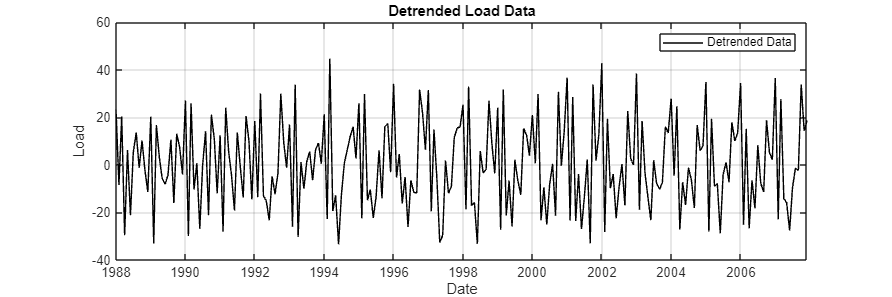

% Plot the detrended data
figure('Position', [100, 100, 1200, 400]);
plot(dailyLoadFactorTable.Date, deTrendedMonthlyLoadFactor, '-k', 'DisplayName', 'Detrended Data');
xlabel('Date');
ylabel('Load');
title('Detrended Load Data');
legend show;
grid on;

## Exponential smoothing of the data

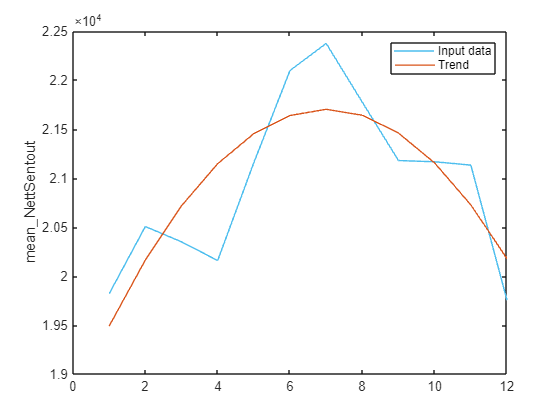

% Remove trend from input data
newTable = detrend(avgLoadPerMonth(:,"mean_NettSentout"),2);

% Extract trend from input data
components = avgLoadPerMonth(:,"mean_NettSentout");
components.(1) = components.(1) - newTable.(1);

% Display results
figure
plot(avgLoadPerMonth.mean_NettSentout,"SeriesIndex",6, ...
    "DisplayName","Input data")
hold on
plot(components.mean_NettSentout,"SeriesIndex",2,"LineWidth",1, ...
    "DisplayName","Trend")
hold off
legend
ylabel("mean_NettSentout","Interpreter","none")

clear newTable